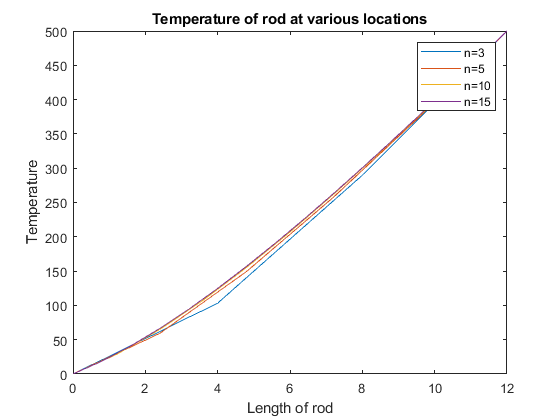

N= [3 5 10 15];

[T1,t1] = BVPsolver(N(1));
[T2,t2] = BVPsolver(N(2));
[T3,t3] = BVPsolver(N(3));
[T4,t4] = BVPsolver(N(4));

figure

plot(t1,T1);
hold on
plot(t2,T2);
hold on
plot(t3,T3);
hold on
plot(t4,T4);
title('Temperature of rod at various locations')
xlabel('Length of rod')
ylabel('Temperature')
legend('n=3','n=5', 'n=10', 'n=15')

function [T, t] = BVPsolver(N)
   dt = 12/N;
   
   plus1 = ones(1,N-2);
   zero = ones(1,N-1);
   zero(1,:) = -2 + 12.5/70*dt;
   minus1 = ones(1,N-2);
   minus1(1,:) = 1 - 12.5/70*dt;
   
   A = diag(plus1,1) + diag(zero,0) + diag(minus1,-1);
   
   b = ones(N-1,1);
   b(1) = 9.81*dt*dt;
   b(2:N-2) = 9.81*dt*dt;
   b(N-1) = 9.81*dt*dt - 500;
   
   SOL = A\b;
   
    T = ones(N+1,1);
    T(1) = 0;
    T(2:N) = SOL;
    T(N+1) = 500;
    
    t = 0:dt:12;
end
